## Krut (10. týden) - 

stejne jako skript na tah (9.tyden) s malymi upravami

clc, clear all, close all;
format shortG;

### Zadani

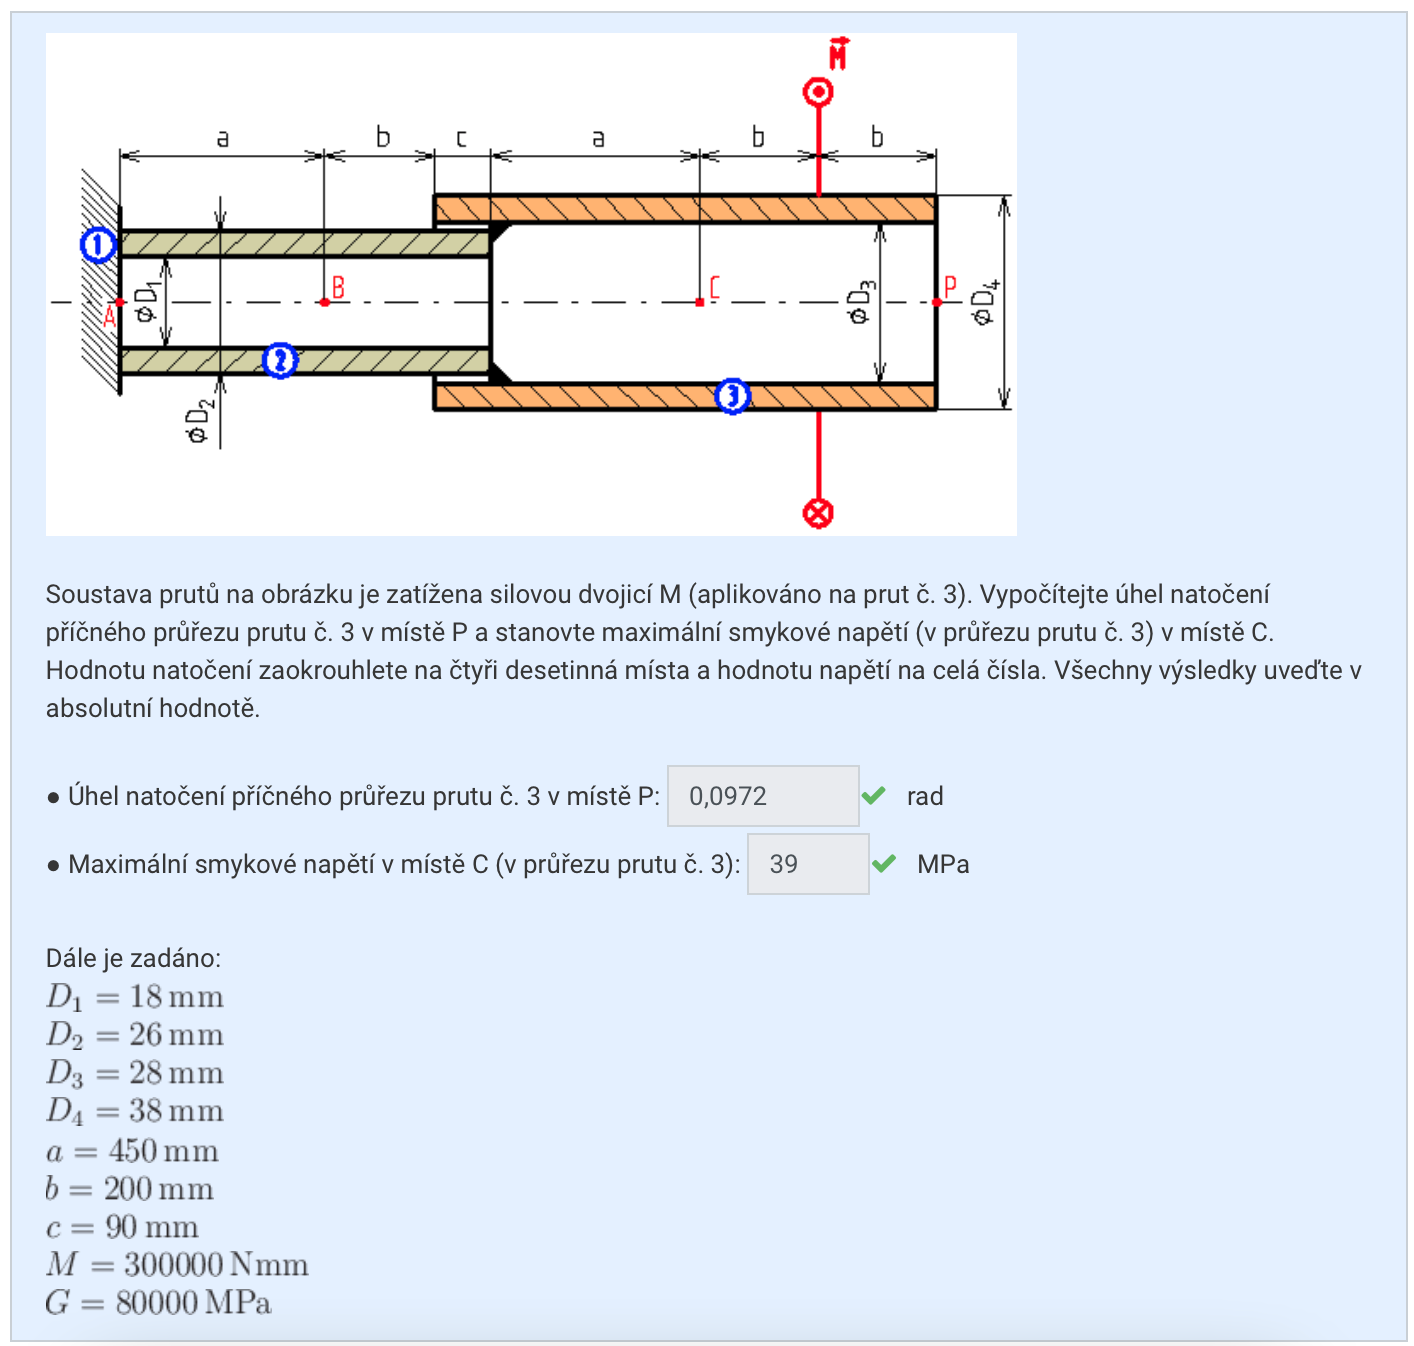

### 1. Popis prutu

#### symbolicke promenne 

syms a b c x % Delkove rozmery
syms D1 D2 D3 D4 % Prumery 
syms M M_svar M_dop1 M_dop2 M_dop3 M_dop4 % V kazdem bode moment - pridavam doplnkove
syms E G % konstanty

#### Numericke promenne - zadani 

% _s jako subsituce 
% 1. ZMENIT HODNOTY ZADANI, nepouzite klidne nechat idc 
a_s = 450;
b_s = 200;
c_s = 90;

D1_s = 18;
D2_s = 26;
D3_s = 28;
D4_s = 38;

M_s = 300000; 
M_dop1_s = 0; % doplnkove momenty nejsou potreba
M_dop2_s = 0;
M_dop3_s = 0;
M_dop4_s = 0;

G_s = 0.8e5;
E_s = 0;

symbolicke_promenne = [a,b,c,D1,D2,D3,D4,M,M_dop1,M_dop2,M_dop3,M_dop4,E,G];
numericke_promenne = [a_s,b_s,c_s,D1_s,D2_s,D3_s,D4_s,M_s,M_dop1_s,M_dop2_s,...
    M_dop3_s,M_dop4_s,E_s,G_s];

#### Plochy pricnych prurezu 

Jp3 = (1/32)*pi*(D4^4 - D3^4); %  Jp telesa 3
Jp2 = (1/32)*pi*(D2^4 - D1^4);

#### VVU

dop. momenty pusobi v kladnem smeru **x - vpravo**

% 2. Zmenit zatizeni a orientaci sil
momenty = [M_dop1,M,M_dop2,M_dop3,M_dop4_s]; % Bez orientace, v ABS hodnote
orientace_momentu = [1,1,1,1,1]; % podle VVU

normalove = construct_VVU_N(momenty,orientace_momentu);

#### Rozlozeni casti prutu

kazdy zacina volnym koncem, postupuje smerem k vetknuti, vsechny 3 vektory musi byt stejne dlouhe

% 3. Zmenit delky useku a jejich prurezy
% Vsechny orientovat stejne, jinac to nebude fungovat
useky = [b,b,a,c+b,a]; % odpovidaji usekum VVU
prurezy = [Jp3,Jp3,Jp3,Jp2,Jp2];
prumery = [D4,D4,D4,D2,D2]; % toto je jenom pro napeti

### 2. Vypocet

#### Potencialni energie napjatosti soustavy 

dW = energie_useku(normalove,G,prurezy);
W = celk_energie(dW,useky,x);

#### POSUVY bodu - Parcialni derivace podle jednotlivych sil 

dW_M = diff_sym_posuv(W,momenty);

#### Natoceni v A,B,C,D vycislene

uhel_p = subs(dW_M,symbolicke_promenne,numericke_promenne);
natoceni = vycisleni(dW_M,symbolicke_promenne,numericke_promenne);
disp("natoceni v bodech P  M  C  SVAR  B ")

natoceni v bodech P  M  C  SVAR  B 


natoceni_zaokrouhlene = abs(round(natoceni,4)) % toto dela i ABS hodnotu

natoceni_zaokrouhlene =        0.0972       0.0972        0.092       0.0803        14578


#### Napeti

tau = napeti_tau(normalove,prurezy,prumery);
napeti_vycislene = abs(vycisleni(tau,symbolicke_promenne,numericke_promenne));
napeti_zaokrouhlene = round(napeti_vycislene,0)

napeti_zaokrouhlene =      0    39    39   113   113


#### Bezpecnost

max_napeti = maxk(napeti_zaokrouhlene,1)

max_napeti =    113


% sigma_k_s =  350e6;
% tau_k = sigma_k_s/2;
% bezpecnost = tau_k / max_napeti;

function energie_telesa_W = celk_energie(A,useky,d_something)        
    zintegrovane = arrayfun(@(dW,a) int(dW,d_something,0,a),A,useky);
    energie_telesa_W = sum(zintegrovane);
end

function vektor_napjatosti = energie_useku(N,E,prurezy)
    vektor_napjatosti = arrayfun(@(N,S) dW_useku(N,E,S),N,prurezy);   
end

function dW = dW_useku(K,KONST,PRUREZ)
    dW = (K^2)/(2*KONST*PRUREZ);
end

function posuvy_symbolicky = diff_sym_posuv(W,sily)
    posuvy_symbolicky = arrayfun(@(F) diff(W,F),sily);
end

function posuvy_numericky = vycisleni(dW_F,sym,num)
    posuvy_numericky = zeros(size(dW_F));
    for i=1:length(dW_F)
        posuvy_numericky(i) = double(subs(dW_F(i),sym,num));
    end

end

function normalove = construct_VVU_N(sily,orientace)
    orientovane_sily = sily.*orientace;
    normalove = sym(zeros(size(sily)));
    for i=1:length(sily)
        normalove(i) = sum(orientovane_sily(1:i));
    end
end

function napeti = napeti_tau(momenty,prurezy,prumery)
    napeti = arrayfun(@(M,Jp,D) ((M/Jp)*(D/2)),momenty,prurezy,prumery);
end